## Part 1 - Formulation

Nodal Equations:

- 
$$0=I_E -\frac{V_2 -V_1 }{\textrm{R1}}-\frac{d\left(V_2 -V_1 \right)}{\textrm{dt}}C\Rightarrow I_E -\frac{V_2 -V_1 }{\textrm{R1}}-j\omega C\left(V_2 -V_1 \right),V_1 =V_{\textrm{in}}$$


- 
$$0=\frac{V_2 -V_1 }{\textrm{R1}}+\frac{d\left(V_2 -V_1 \right)}{\textrm{dt}}C+\frac{V_2 }{\textrm{R2}}+I_L \Rightarrow 0=\frac{V_2 -V_1 }{\textrm{R1}}+j\omega C\left(V_2 -V_1 \right)+\frac{V_2 }{\textrm{R2}}+\frac{V_2 -V_3 }{j\omega L}$$


- 0 = $\frac{V_3 }{\textrm{R3}}-I_L \Rightarrow 0=\frac{V_3 }{\textrm{R3}}-\frac{V_2 -V_3 }{j\omega L}$

- 
$$V_4 =\alpha I_3 =\alpha \;\frac{V_3 }{R_3 }$$


- 
$$0=\frac{V_4 -V_5 }{\textrm{R4}}-\frac{V_5 }{\textrm{R0}}//V_5 =V_4 \frac{\textrm{R0}}{\textrm{R4}+\textrm{R0}}$$


## Part 2 - Programming

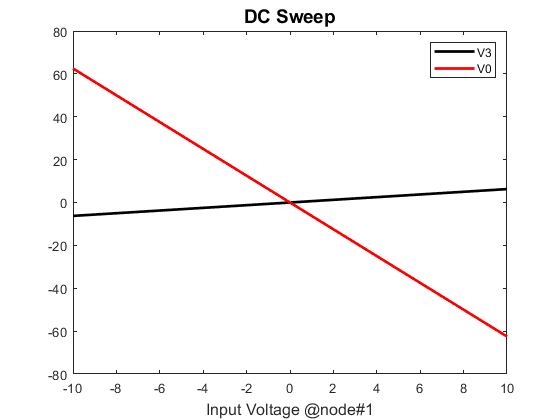

clc; close all; clear all;
set(0, 'DefaultFigureWindowStyle', 'docked')
global G C F
% syms v1 v2 v3 v4 v5 IE IL I3

R1 = 1;
R2 = 2;
R3 = 10;
R4 = 0.1;
R0 = 1000;
C1 = 0.25;
L1 = 0.2;
alpha = 100;

% MNA Formulation
F = [0;0;0;0;0;1;0;0];  % Stimuli

G = [   % Conductance
    1/R1,-1/R1,0,0,0,1,0,0;
    -1/R1,1/R1+1/R2,0,0,0,0,1,0;
    0,0,1/R3,0,0,0,-1,0;
    0,0,0,1/R4,-1/R4,0,0,1;
    0,0,0,-1/R4,1/R4-1/R0,0,0,0;
    1,0,0,0,0,0,0,0;
    0,1,-1,0,0,0,0,0;
    0,0,alpha/R3,1,0,0,0,0;
    ];

C = [   % Energy Storage
    C1,-C1,0,0,0,0,0,0;
    -C1,C1,0,0,0,0,0,0;
    0,0,0,0,0,0,0,0;
    0,0,0,0,0,0,0,0;
    0,0,0,0,0,0,0,0;
    0,0,0,0,0,0,0,0;
    0,0,0,0,0,0,-L1,0;
    0,0,0,0,0,0,0,0;
    ];

% DC Sweep
s = 0;
vin = linspace(-10,10,100);
V3 = zeros(size(vin));
V0 = zeros(size(vin));
for i = 1:size(vin,2)
    V = (G+s.*C)\(F.*vin(i));   % Solving
    V3(i) = V(3);
    V0(i) = V(5);
end
figure('name',"DC Sweep")
plot(vin,V3,'k',"LineWidth",2);
hold on
plot(vin,V0,'r',"LineWidth",2);
hold off
xlabel('Input Voltage @node#1','FontSize',12);
legend('V3','V0'), title('DC Sweep', 'FontSize',14);

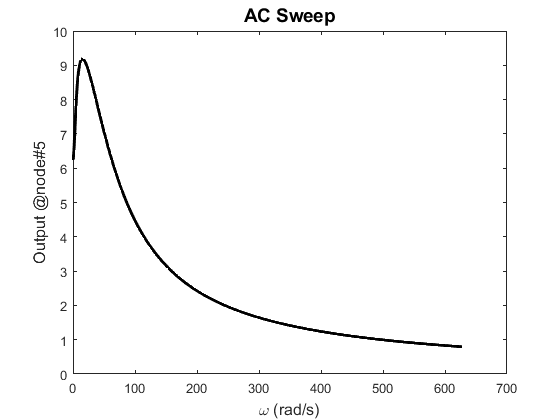


% AC Sweep
f = linspace(0.001, 100, 100000);
V0 = zeros(size(f));
for i = 1:size(f,2)
    w = 2*pi*f(i);
    s = 1i*w;
    V = (G+s*C)\F;  % Solving
    V0(i) = V(5);
end
figure("Name","AC Sweep")
plot(2*pi*f,abs(V0),'k',"LineWidth",2);
title('AC Sweep', 'FontSize',14);
xlabel('\omega (rad/s)','FontSize',12);
ylabel('Output @node#5','FontSize',12);

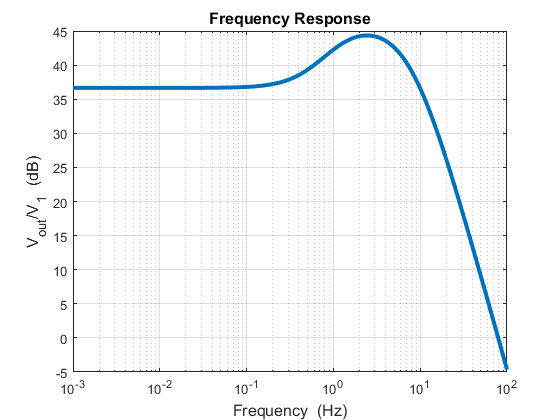

figure('Name','Freq-Response');
semilogx(f, 20*log(abs(V0)),'LineWidth',3);
grid;
title('Frequency Response', 'FontSize',12);
xlabel('Frequency  (Hz)','FontSize',12);
ylabel('V_{out}/V_{1}  (dB)','FontSize',12);

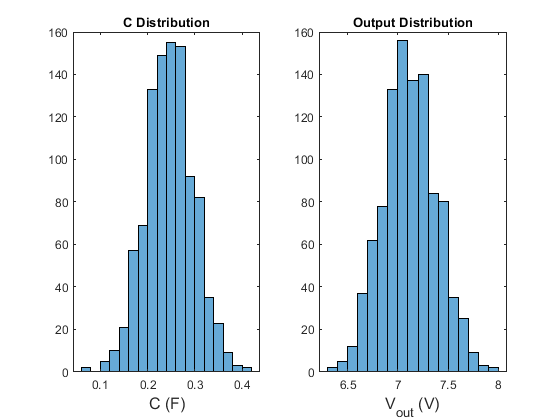


% Monte Carlo Analysis of C
s = 1i*pi;
C1_dist = C1 + 0.05 * randn(1000,1);
V0 = zeros(size(C1_dist));
for i = 1:size(C1_dist,1)
    C(1,1) = C1_dist(i);
    C(1,2) = -C1_dist(i);
    C(2,1) = -C1_dist(i);
    C(2,2) = C1_dist(i);
    V = (G+s*C)\F;  % Solving
    V0(i) = V(5);
end
figure("Name","Monte Carlo Analysis of C")
subplot(1,2,1), histogram(C1_dist);
title('C Distribution', 'FontSize',14);
xlabel('C (F)','FontSize',12);
subplot(1,2,2), histogram(abs(V0));
title('Output Distribution', 'FontSize',14);
xlabel('V_{out} (V)','FontSize',12);